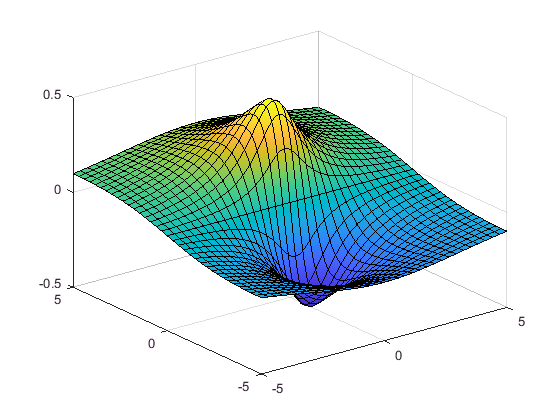

syms x y;
z = y/(1+x^2+y^2);
fsurf(z);

syms x;
limit(sin(x)/x, x,0)

$$ans = 1$$

syms x y;
f = sin(x);
diff(f,'x', 2)

$$ans = -\sin\left(x\right)$$

f2 = y*sin(x) + x*cos(y);
diff(f2)

$$ans = \cos\left(y\right)+y\,\cos\left(x\right)$$

syms x y x;
f1 = 2*x/(1+x^2)^2;
int(f1)

$$ans = -\frac{1}{x^{2}+1}$$

syms x;
taylor(sin(x), x, 'Order', 12)

$$ans = -\frac{x^{11}}{39916800}+\frac{x^{9}}{362880}-\frac{x^{7}}{5040}+\frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

taylor(exp(x), 'Order', 5)

$$ans = \frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$


f = x*sin(x);
ft = taylor(f, 'Order', 18);
ft

$$ft = -\frac{x^{16}}{1307674368000}+\frac{x^{14}}{6227020800}-\frac{x^{12}}{39916800}+\frac{x^{10}}{362880}-\frac{x^{8}}{5040}+\frac{x^{6}}{120}-\frac{x^{4}}{6}+x^{2}$$

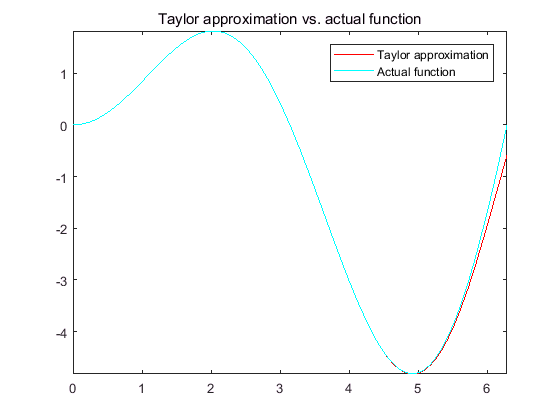

fplot(ft, [0, 2*pi], 'r');
hold on;
fplot(f, [0, 2*pi], 'c');
legend('Taylor approximation', 'Actual function');
title('Taylor approximation vs. actual function');
hold off;

syms x y a b c v u;
out = solve(a*x^2+b*x+c);
% out = solve('a*x^2+b*x+c');
out

$$out = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

disp('-----------');

-----------


% formula group
out = solve(x+2*y-u, 4*x+5*y-v);
out

out = 包含以下字段的 struct :
    x: [1×1 sym]
    y: [1×1 sym]


disp(out.x);

$$\frac{2\,v}{3}-\frac{5\,u}{3}$$

disp(out.y);

$$\frac{4\,u}{3}-\frac{v}{3}$$

disp('-----------')

-----------


syms x y alpha;
[x, y] = solve(x^2*y*2, x-y/2-alpha);
disp(x);

$$\left(\begin{array}{c} 0\\ \alpha \end{array}\right)$$

disp(y);

$$\left(\begin{array}{c} -2\,\alpha \\ 0 \end{array}\right)$$


disp('------------');

------------


dsolve('Dx=cos(t)')

$$ans = C_{7}+\sin\left(t\right)$$

dsolve('D2x=cos(t)')
dsolve('(Dx)^2+x^2=1')
% with init value

$$ans = C_{9}-\cos\left(t\right)+C_{8}\,t$$

$$ans = \left(\begin{array}{c} 1\\ -1\\ \frac{{\mathrm{e}}^{C_{14}\,\mathrm{i}+t\,\mathrm{i}}\,\left({\mathrm{e}}^{-2\,C_{14}\,\mathrm{i}-2\,t\,\mathrm{i}}+1\right)}{2}\\ \frac{{\mathrm{e}}^{C_{11}\,\mathrm{i}-t\,\mathrm{i}}\,\left({\mathrm{e}}^{-2\,C_{11}\,\mathrm{i}+2\,t\,\mathrm{i}}+1\right)}{2} \end{array}\right)$$

dsolve('Dx=a*x', 'x(0)=b')

$$ans = b\,{\mathrm{e}}^{a\,t}$$

syms f g;
S = dsolve('Df=3*f+4*g', 'Dg=-4*f+3*g');
disp(S);

    g: [1×1 sym]
    f: [1×1 sym]



disp(S.f);

$$C_{24}\,\cos\left(4\,t\right)\,{\mathrm{e}}^{3\,t}+C_{23}\,\sin\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

disp(S.g);

$$C_{23}\,\cos\left(4\,t\right)\,{\mathrm{e}}^{3\,t}-C_{24}\,\sin\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$